b = 1.02;
c = 0.08;
lambda = pi/10;
h = 0.856;

V = 12.22;
a = 0.347;

sys_tf = get_bicycle_no_fb_tf(h, V, a,b,c,lambda);
sys_tf

sys_tf =
 
  1.501 s + 52.74
  ---------------
    s^2 - 11.46
 
Continuous-time transfer function.



% bode(sys_tf);

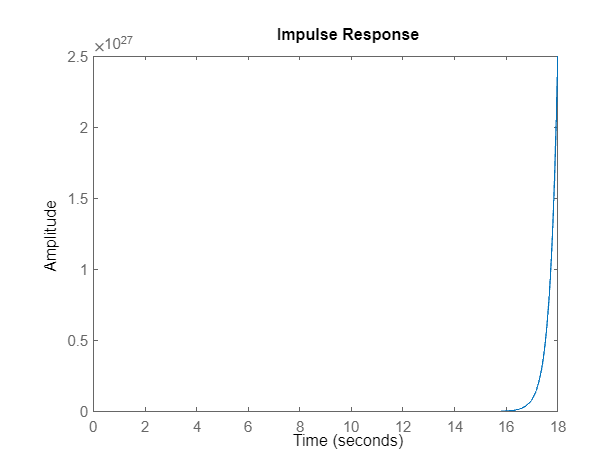

impulse(sys_tf);

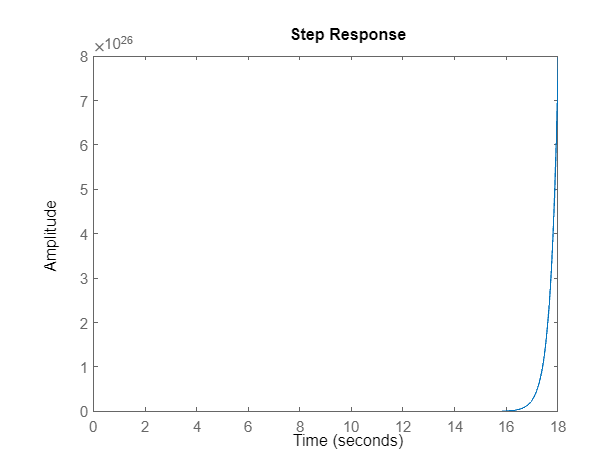

step(sys_tf);

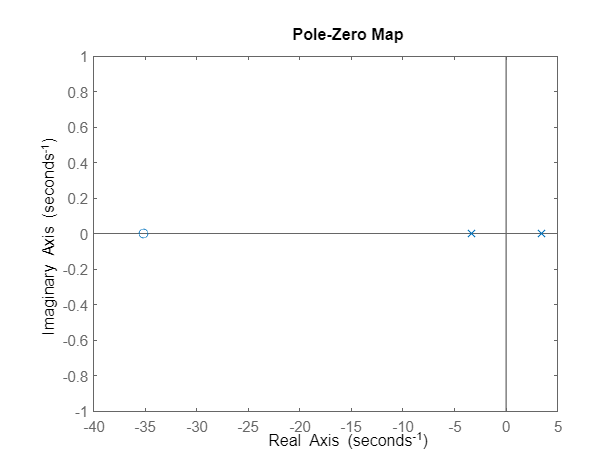

pzmap(sys_tf);

% rlocus(sys_tf);

% nyquist(sys_tf);

% nichols(sys_tf);

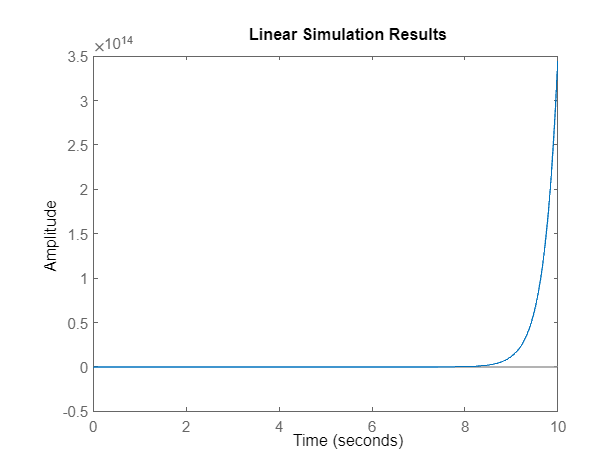

t = 0:0.01:10; % Time vector
u = sin(t); % Example input
lsim(sys_tf, u, t);